%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  Numerical Method 2021 
%  Extra Credit Assignment 
%  by Y K KIM
%  2021-6-15
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

close all;  clc; clear;

## Load Raw Data

load('LIDAR_ROI.mat')
Xdata=LIDAR_ROI(1,:)';
Ydata=LIDAR_ROI(2,:)';
Zdata=LIDAR_ROI(3,:)';

## Fit Plane using Least Regression

ax+by+cz+d=0; where y=depth, z=vertical 

% [plane,nvec_param]=fitPlaneLiDAR2(Xdata, -1*Ydata, Zdata); 
%  nv_plane=nvec_param(1:3);    % nv_plane=[a, b, c]
%  d_plane=nvec_param(4);

## Calculate Plane Angle

% nv_plane_norm=nv_plane/norm(nv_plane);
% a=nv_plane_norm(1);b=nv_plane_norm(2);c=nv_plane_norm(3);
% alpha = atan2d(c,b)     % =atan(c/b) : x축의 회전각 (y-z 평면의 각도) [deg]
% beta  = atan2d(a,c)     % =atan(a/c) : y축의 회전각 (z-x 평면의 각도) [deg]
% gamma = atan2d(b,a)     % =atan(b/a) : z축의 회전각 (x-y 평면의 각도) [deg]
% aiming_plane=90-gamma
% tilt_plane=alpha

## Plot data point and plane surface

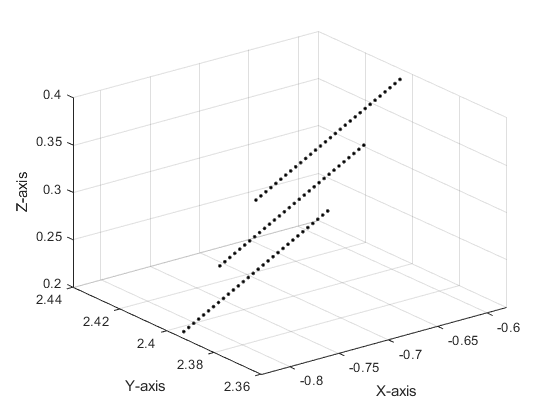

% Generate Plane
A=-0.179047;
B=1;
C=0.176327;
D=-2.577728;
X=-0.85:0.01:-0.55;
Y=2.35:0.01:2.45;
[x y] = meshgrid(X,Y);      
z = -1/C*(A*x + B*y + D);   

% Plot scan lines
figure
plot3(Xdata, Ydata, Zdata, 'k.')
grid on
xlabel('X-axis')
ylabel('Y-axis')
zlabel('Z-axis')

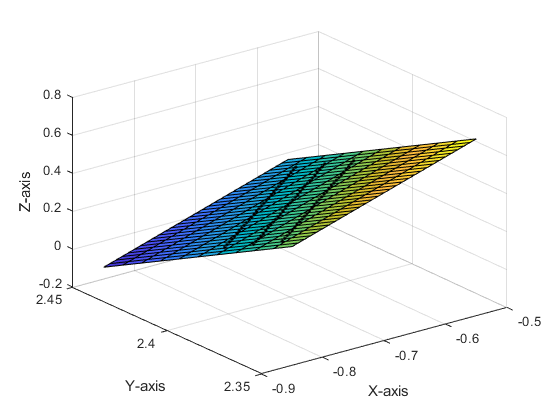


% Plot plane surface and scan lines
figure
plot3(Xdata, Ydata, Zdata, 'k.')
grid on
xlabel('X-axis')
ylabel('Y-axis')
zlabel('Z-axis')
hold on
surf(x,y,z) 
hold off